# Basics Of Fourier Series:

### What is Fourier Series?

watch [this video](https://www.youtube.com/watch?v=r6sGWTCMz2k) to understand fourier series better.

The following sections will contains different example of plotting Fourier Series with different Functions. We are using Matlab as a Tool here.

#### Function : This example fits the El Nino-Southern Oscillation (ENSO) data. The ENSO data consists of monthly averaged atmospheric pressure differences between Easter Island and Darwin, Australia. This difference drives the trade winds in the southern hemisphere.

load enso;

You can change the number of coefficient to be used by adjusting the dropdown.

f = fit(month,pressure,"fourier8")

f =      General model Fourier8:
     f(x) = 
               a0 + a1*cos(x*w) + b1*sin(x*w) + 
               a2*cos(2*x*w) + b2*sin(2*x*w) + a3*cos(3*x*w) + b3*sin(3*x*w) + 
               a4*cos(4*x*w) + b4*sin(4*x*w) + a5*cos(5*x*w) + b5*sin(5*x*w) + 
               a6*cos(6*x*w) + b6*sin(6*x*w) + a7*cos(7*x*w) + b7*sin(7*x*w) + 
               a8*cos(8*x*w) + b8*sin(8*x*w)
     Coefficients (with 95% confidence bounds):
       a0 =       10.63  (10.28, 10.97)
       a1 =      0.5668  (0.07981, 1.054)
       b1 =      0.1969  (-0.2929, 0.6867)
       a2 =      -1.203  (-1.69, -0.7161)
       b2 =     -0.8087  (-1.311, -0.3065)
       a3 =      0.9321  (0.4277, 1.436)
       b3 =      0.7602  (0.2587, 1.262)
       a4 =     -0.6653  (-1.152, -0.1788)
       b4 =     -0.2038  (-0.703, 0.2954)
       a5 =    -0.02919  (-0.5158, 0.4575)
       b5 =     -0.3701  (-0.8594, 0.1192)
       a6 =    -0.04856  (-0.5482, 0.4511)
       b6 =     -0.1368  (-0.6317, 0.3581)
       a7 =       2.811

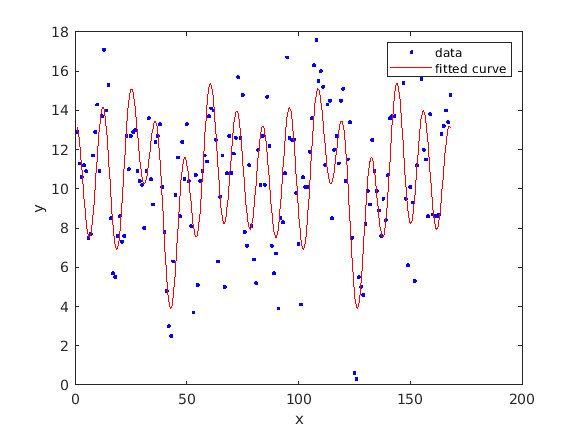

plot(f,month,pressure)

The coefficient values are printed below.

coeffvalues(f)

ans =    10.6261    0.5668    0.1969   -1.2031   -0.8087    0.9321    0.7602   -0.6653   -0.2038   -0.0292   -0.3701   -0.0486   -0.1368    2.8112    1.3344    0.0798   -0.1076    0.0753
